It.: 1 Compl.: 4.0055e-02 Vol.:   1.00
It.: 2 Compl.: 4.0055e-02 Vol.:   1.00
It.: 3 Compl.: 4.0055e-02 Vol.:   1.00
It.: 4 Compl.: 4.0055e-02 Vol.:   1.00
It.: 5 Compl.: 4.0055e-02 Vol.:   1.00
It.: 6 Compl.: 4.0055e-02 Vol.:   1.00
It.: 7 Compl.: 4.0055e-02 Vol.:   1.00
It.: 8 Compl.: 4.0056e-02 Vol.:   1.00
It.: 9 Compl.: 4.0064e-02 Vol.:   0.98
It.: 10 Compl.: 4.0089e-02 Vol.:   0.97
It.: 11 Compl.: 4.0200e-02 Vol.:   0.96
It.: 12 Compl.: 4.0242e-02 Vol.:   0.95
It.: 13 Compl.: 4.0333e-02 Vol.:   0.94
It.: 14 Compl.: 4.0433e-02 Vol.:   0.92
It.: 15 Compl.: 4.0543e-02 Vol.:   0.91
It.: 16 Compl.: 4.0668e-02 Vol.:   0.91
It.: 17 Compl.: 4.0789e-02 Vol.:   0.90
It.: 18 Compl.: 4.0903e-02 Vol.:   0.89
It.: 19 Compl.: 4.1007e-02 Vol.:   0.89
It.: 20 Compl.: 4.1125e-02 Vol.:   0.89
It.: 21 Compl.: 4.1190e-02 Vol.:   0.88
It.: 22 Compl.: 4.1299e-02 Vol.:   0.88
It.: 23 Compl.: 4.1380e-02 Vol.:   0.88
It.: 24 Compl.: 4.1505e-02 Vol.:   0.87
It.: 25 Compl.: 4.1603e-02 Vol.:   0.87
It.: 26 C

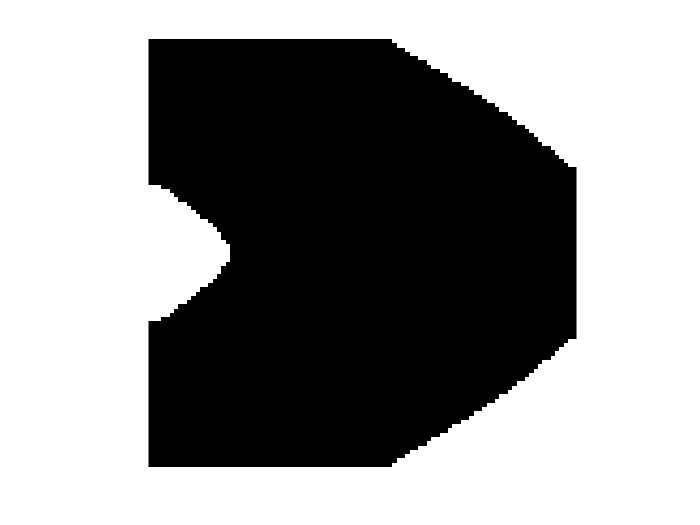

% Matlab code for topology optimization using a reaction diffusion equation

levelset88(100,100,1,5e-4);

function [str,phi] = levelset88(nelx,nely,Vmax,tau)
    %% Parameter definition
    E0 = 1;
    Emin = 1e-4;
    nu = 0.3;
    nvol = 100;
    dt = 0.1;
    d = -0.02;
    p = 4;
    phi = ones((nely+1)*(nelx+1),1);
    str = ones(nely,nelx);
    volInit = sum(str(:))/(nelx*nely);
    %% Finite element analysis preparation
    % For displacement field
    A11 = [12 3 -6 -3; 3 12 3 0; -6 3 12 -3; -3 0 -3 12];
    A12 = [-6 -3 0 3; -3 -6 -3 -6; 0 -3 -6 3; 3 -6 3 -6];
    B11 = [-4 3 -2 9; 3 -4 -9 4; -2 -9 -4 -3; 9 4 -3 -4];
    B12 = [ 2 -3 4 -9; -3 2 9 -2; 4 9 2 3; -9 -2 3 2];
    KE = 1/(1-nu^2)/24*([A11 A12;A12' A11]+nu*[B11 B12;B12' B11]);
    % For Topological derivative
    a1 = 3*(1-nu)/(2*(1+nu)*(7-5*nu))*(-(1-14*nu+15*nu^2)*E0)/(1-2*nu)^2;
    a2 = 3*(1-nu)/(2*(1+nu)*(7-5*nu))*5*E0;
    A = (a1+2*a2)/24*([A11 A12;A12' A11]+(a1/(a1+2*a2))*[B11 B12;B12' B11]);
    nodenrs = reshape(1:(1+nelx)*(1+nely),1+nely,1+nelx);
    edofVec = reshape(2*nodenrs(1:end-1,1:end-1)+1,nelx*nely,1);
    edofMat = repmat(edofVec,1,8)+repmat([0 1 2*nely+[2 3 0 1] -2 -1],nelx*nely,1);
    iK = reshape(kron(edofMat,ones(8,1))',64*nelx*nely,1);
    jK = reshape(kron(edofMat,ones(1,8))',64*nelx*nely,1);
    % For Reaction diffusion equation
    NNdif_e = 1/6*[ 4 -1 -2 -1;-1 4 -1 -2;-2 -1 4 -1;-1 -2 -1 4];
    NN_e = 1/36*[ 4 2 1 2;2 4 2 1;1 2 4 2;2 1 2 4];
    edofVec2= reshape(nodenrs(1:end-1,1:end-1)+1,nelx*nely,1);
    edofMat2= repmat(edofVec2,1,4)+repmat([0 nely+1 nely -1],nelx*nely,1);
    iN = reshape(kron(edofMat2,ones(4,1))',16*nelx*nely,1);
    jN = reshape(kron(edofMat2,ones(1,4))',16*nelx*nely,1);
    sNN = reshape(NN_e(:)*ones(1,nely*nelx),16*nelx*nely,1);
    NN = sparse(iN,jN,sNN);
    sNNdif = reshape(NNdif_e(:)*ones(1,nely*nelx),16*nelx*nely,1);
    NNdif = sparse(iN,jN,sNNdif);
    %% Loads and boundary settings
    F = sparse(2*(nely+1)*(nelx+1),1);
    U = zeros(2*(nely+1)*(nelx+1),1);
    F((nely+1)*(nelx)*2+nely+2*(-round(nely/32)+1):2:(nely+1)*(nelx)*2+nely+2*(round(nely/32)+1),1) = 1;
    fixeddofs = 1:2*(nely+1);
    alldofs = 1:2*(nely+1)*(nelx+1);
    freedofs = setdiff(alldofs,fixeddofs);
    T = NN/dt + tau*(nely*nelx)*NNdif;
    fixeddofs_phi = sort([1:nely+1 nely+2:nely+1:(nely+1)*(nelx) 2*(nely+1):nely+1:(nely+1)*(nelx) ...
    (nely+1)*nelx+1:(nely+1)*(nelx+1)]);
    phi(fixeddofs_phi) = 0;
    alldofs_phi = 1:(nely+1)*(nelx+1);
    freedofs_phi = setdiff(alldofs_phi,fixeddofs_phi);
    %% Main loop
    for iterNum = 1:200
        % FE-analysis, calculate sensitivities
        sK = reshape(KE(:)*(Emin+str(:)'*(E0-Emin)),64*nelx*nely,1);
        K = sparse(iK,jK,sK);
        K = (K+K')/2;
        U(freedofs) = K(freedofs,freedofs) \ F(freedofs);
        SED = (Emin+str*(E0-Emin)).*reshape(sum((U(edofMat)*KE).*U(edofMat),2),nely,nelx);
        TD = (1e-4+str*(1-1e-4)).*reshape(sum((U(edofMat)*A).*U(edofMat),2),nely,nelx);
        td2=[TD(1,1) TD(1,:) TD(1,end); TD(:,1) TD TD(:,end) ; TD(end,1) TD(end,:) TD(end,end)];
        TDN = 0.25*(td2(1:end-1,1:end-1)+td2(2:end,1:end-1)+td2(1:end-1,2:end)+td2(2:end,2:end));
        objective(iterNum) = sum(SED(:));
        vol = sum(str(:))/(nelx*nely);
        % Print results
        disp(['It.: ' num2str(iterNum) ' Compl.: ' sprintf('%10.4e',objective(iterNum)/((nelx*nely)))...
            ' Vol.: ' sprintf('%6.2f' ,vol)])
        colormap(gray); imagesc(-str,[-1,0]); axis equal; axis tight; axis off; drawnow;
        % Check for convergence
        if iterNum>nvol && (abs(vol-Vmax)<0.005) && all(abs(objective(end)- ...
                objective(end-5:end-1))< 0.01*abs(objective(end)))
            return;
        end
        % Set augmented Lagrangian parameters
        ex = Vmax+(volInit-Vmax)*max(0,1-iterNum/nvol);
        lambda = sum(sum(TDN))/((nely+1)*(nelx+1))*exp(p*((vol-ex)/ex+d));
        C = 1/sum(abs(TDN(:)))*(nely*nelx);
        g2 = reshape(TDN,(nely+1)*(nelx+1),1);
        % Update level set function
        Y = NN*(C*(g2-lambda*ones(size(g2)))+phi/dt);
        phi(freedofs_phi,:) = T(freedofs_phi,freedofs_phi) \ Y(freedofs_phi,:);
        phi = min(1,max(-1,phi));
        phin = reshape(phi,nely+1,nelx+1);
        phie = 0.25*(phin(1:end-1,1:end-1)+phin(2:end,1:end-1)+phin(1:end-1,2:end)+phin(2:end,2:end));
        str(:,:) = (phie(:,:)>0);
    end
end